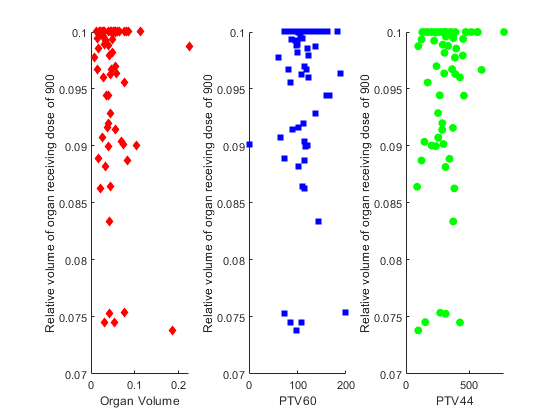

% INITIALIZATION
clear all;
clc
%-------------------------------------------
% LOAD THE DATA FILE IN X and Y VARIABLE
%-------------------------------------------
data = load('Group_2.txt');
X = data(:, 1:3);           % X contain array of Organ Volume,PTV60 and PTV44
y = data(:, 4);             % y contain array of Relative volume of organ receiving dose of 900
m = length(y);              % NUMBER OF DATA
%-------------------------------------------
% PLOT DATA
%-------------------------------------------
figure
subplot(1,3,1)
scatter(X(:,1), y/1000,'diamond','filled','MarkerFaceColor','r');            % Here, plotData is an external function to plot Organ Volume vs Relative volume of organ receiving dose of 900e
xlabel('Organ Volume')
ylabel('Relative volume of organ receiving dose of 900')
subplot(1,3,2)
scatter(X(:,2), y/1000,'square','filled','MarkerFaceColor','b');             % Here, plotData is an external function to plot PTV60 vs Relative volume of organ receiving dose of 900
xlabel('PTV60')
ylabel('Relative volume of organ receiving dose of 900')
subplot(1,3,3)
scatter(X(:,3), y/1000,'filled','MarkerFaceColor','g');                      % Here, plotData is an external function to plot PTV44 vs Relative volume of organ receiving dose of 900
xlabel('PTV44')
ylabel('Relative volume of organ receiving dose of 900')

**Next, we obtain the z-score (or normalized value). By looking at the graph above, we can identify that house size in 1000 times greater than number of rooms. In such case, we perform scaling of the x-values to attain a faster convergence using gradient descent method.**

$Z-\textrm{score}\;\left\lbrack \textrm{or}\;X_{\textrm{normalized}} \left(i\right)\right\rbrack =\frac{X_m \left(i\right)-\bar{X_m \left(i\right)} }{\sigma \left(X_m \left(i\right)\right)}$                                                             **(1)**

**where, i is the number of row or data in one input variable, m is the number of input variable (=2), **$X_m \left(i\right)$** actual data set, **$\bar{X_m \left(i\right)}$**  is the mean value of **$X_m \left(i\right)$** array, **$\sigma \left(X_m \left(i\right)\right)$** standard deviation of **$X_m \left(i\right)$** array. The mean and standard deviation can be calculated using the formula**

         $\textrm{Mean}\;\left\lbrack \textrm{or}\;\;\bar{X_m \left(i\right)} \right\rbrack =\frac{\sum_{i=1}^N X_m \left(i\right)\;\;}{N}$                                                                        **(2)**

            $\sigma \;\left\lbrack X_m \left(i\right)\right\rbrack =\sqrt{\frac{X_m \left(i\right)-\bar{X_m \left(i\right)} }{N}}$                                                                           **(3)**

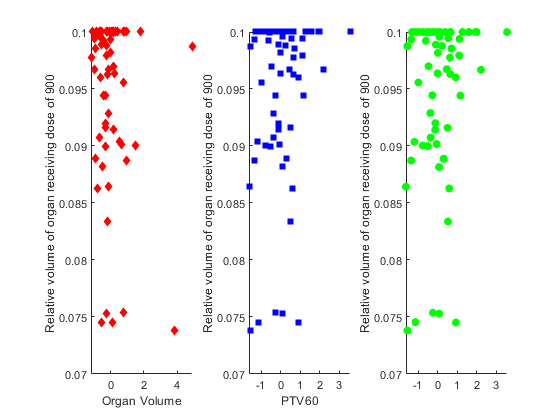

for i  = 1:size(X,2)                      % i is column 1,2 and 3 (i.e., three variables)
    mu(i) = mean(X(:,i));                   % mean of total number of rows (corresponding to 3 column)
    sigma(i) = std(X(:,i));                 % standard deviation of total number of rows (corresponding to 3 column)
    X_norm(:,i)= (X(:,i)-mu(i))/sigma(i);   % Z-score or normalized data (corresponding to three columns)
end
%-------------------------------------------
% PLOT THE NORMALIZED DATA
%-------------------------------------------
figure
subplot(1,3,1)
scatter(X_norm(:,1), y/1000,'diamond','filled','MarkerFaceColor','r');            % Here, plotData is an external function to plot Organ Volume vs Relative volume of organ receiving dose of 900e
xlabel('Organ Volume')
ylabel('Relative volume of organ receiving dose of 900')
subplot(1,3,2)
scatter(X_norm(:,3), y/1000,'square','filled','MarkerFaceColor','b');             % Here, plotData is an external function to plot PTV60 vs Relative volume of organ receiving dose of 900e
xlabel('PTV60')
ylabel('Relative volume of organ receiving dose of 900')
subplot(1,3,3)
scatter(X_norm(:,3), y/1000,'filled','MarkerFaceColor','g');                       % Here, plotData is an external function to plot PTV44 vs Relative volume of organ receiving dose of 900e
ylabel('Relative volume of organ receiving dose of 900')

% GRADIENT DESCENT FORMULATION AND ITERATION
X = [ones(m, 1) X_norm];        % ADD INTERCEPT 1 FOR X data file
                                %
theta = zeros(4, 1);            % Similarly, the array theta (i.e., both theta_0,theta_1,theta_2 and theta_3)
                                % are initialize as zeros
% SOME ITERATION SETTINGS
iterations = 800;               % Maximum number of iteration or termination condition
alpha = 0.01;                   % Learning rate or correction factor
%
% RUN GRADIENT DESCENT BY CALLING FUNCTION
[theta_new, J_history] = gradientDescent(X, y, theta, alpha, iterations);
% PRINT THETA_NEW AT THE END OF ITERATION ON SCREEN
fprintf('Theta found by gradient descent (theta_0 & theta_1 & theta_2 & theta_3):\n'); fprintf('%f\n', theta_new(iterations,:));

Theta found by gradient descent (theta_0 & theta_1 & theta_2 & theta_3):
94.800366
-1.169533
0.407477
0.577144


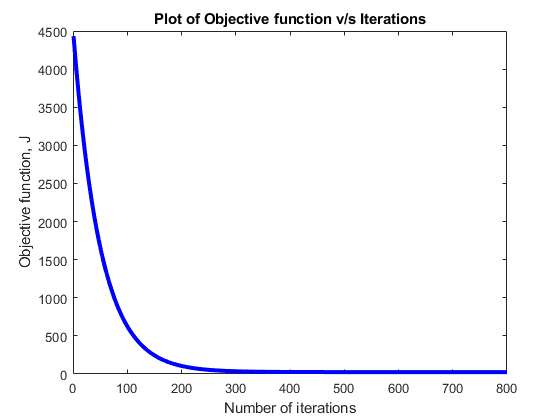

% PLOT THE CONVERGENCE CURVE
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 3);
xlabel('Number of iterations');
ylabel('Objective function, J');
title('Plot of Objective function v/s Iterations');


data_test = load('test_data.txt')  %load the new data 

data_test =     0.0578   86.3000  100.4000
    0.0598  134.3000  234.1000
    0.0391   93.0000  247.9000
    0.0508  111.1000  198.7000
    0.0380  141.2000  328.6000
    0.0423  154.3000  492.0000
    0.0605  133.1000  208.1000
    0.0734   88.6000   89.9000
    0.0363   89.1000  273.0000
    0.0970   93.2000  102.1000


X_new = data_test(:, 1:3)

X_new =     0.0578   86.3000  100.4000
    0.0598  134.3000  234.1000
    0.0391   93.0000  247.9000
    0.0508  111.1000  198.7000
    0.0380  141.2000  328.6000
    0.0423  154.3000  492.0000
    0.0605  133.1000  208.1000
    0.0734   88.6000   89.9000
    0.0363   89.1000  273.0000
    0.0970   93.2000  102.1000


     for i  = 1:size(X_new,2)   
      mu_2(i) = mean(X_new(:,i)); 
      sigma(i) = std(X_new(:,i));                  
      X_new_norm(:,i)= (X_new(:,i)-mu_2(i))/sigma(i);
     end
              
% ADD INTERCEPT FOR X_new_norm
X_new = [ones(size(X_new_norm(:, 1:3),1), 1) X_new_norm(:, 1:3)]

X_new =     1.0000    0.1196   -1.0091   -1.0386
    1.0000    0.2270    0.8453    0.0541
    1.0000   -0.8645   -0.7502    0.1669
    1.0000   -0.2467   -0.0510   -0.2352
    1.0000   -0.9220    1.1118    0.8265
    1.0000   -0.6983    1.6179    2.1620
    1.0000    0.2663    0.7989   -0.1584
    1.0000    0.9456   -0.9202   -1.1245
    1.0000   -1.0158   -0.9009    0.3720
    1.0000    2.1889   -0.7425   -1.0247


y_new = X_new*theta_new(iterations,:)';         % Prediction y = theta_0+theta_1*X1+theta_2*X2+theta_3*X3;

y_new

y_new =    93.6499
   94.9105
   95.6021
   94.9324
   96.8087
   97.5241
   94.7230
   92.6705
   95.8360
   91.3464
